# Modelo 2

Modelo de crecimiento lineal.

En este modelo también se saca dinero. En concreto hacemos un gasto $s$ por mes.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=k-s\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$



$$\begin{array}{l}
k\;\;\;\;\;\;\;\;=\textrm{cantidad}\;\textrm{depositada}\;\textrm{mensualmente}\\
M\left(t\right)=\textrm{cantidad}\;\textrm{de}\;\textrm{dinero}\;\textrm{en}\;\textrm{la}\;\textrm{cuenta}\;\textrm{en}\;\textrm{un}\;\textrm{instante}\;t\\
s\;\;\;\;\;\;\;=\textrm{cantidad}\;\textrm{de}\;\textrm{gasto}\;\textrm{mensual}
\end{array}$$


#### 1. Sustitución de valores iniciales y constante k

clc, clear

syms M(t) k M0 t0 s 

edo = diff(M, t, 1) == k - s;

cond = [M(t0)==M0];

M(t) = dsolve(edo, cond);
M(t) = collect(M(t), [k, s])     % para sacar factor comun

$$M(t) = \left(t-t_{0}\right)\,k+\left(t_{0}-t\right)\,s+M_{0}$$

#### 2. Sustitución de valores iniciales y constante k

k_values =  [2, 3, -2];
s_values = [4, 1, -2];
ic_values = [0 1; 0 8; 0 5];
t_values = 0:5:10;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso

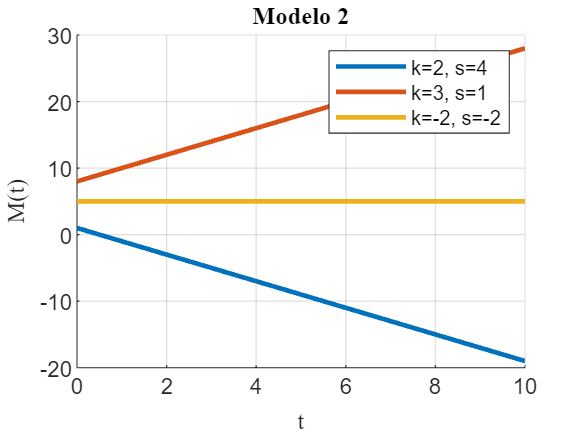

figure;
hold on;

for i = 1:n
    M_subs = subs(M, [k s], [k_values(i) s_values(i)]);
    M_subs = subs(M_subs, [t0, M0], [ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i)) ', s=' num2str(s_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 2','FontName','latex');
legend('show');
grid on;
hold off;

Estamos ante un modelo de crecimiento lineal. Para:

$k>s$ crecimiento (ahorramos más que gastamos)

$k<s$ decrecimiento (gastamos más que ahorramos)

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=k-s\\
k=s
\end{array}$$


syms M k s
eq = k - s == 0;
k = solve(eq,k)

$$k = s$$

La estabilidad solo se alcanza si $k=s$ ya que, entonces gastamos lo mismo que ahorramos.